参考代码的使用

对于type 2或以上的系统，一定会产生overshoot


$$P\left(s\right)=\frac{2s+10}{s^2 \left(s+1\right)}$$


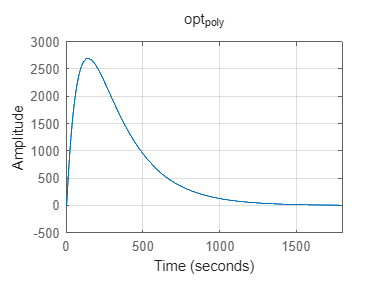

clf; clear;
denum = [1,1,0,0];
num = [1 10];
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("opt_{poly}");
grid on;

我的代码使用

clf; clear;
denum = [1,1,0,0];
num = [1 10];
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


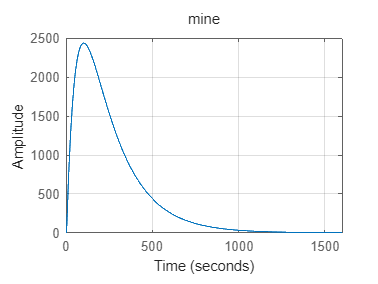

[C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = giveTransferFunction(C1,C2,Plant);
step(T)
title("mine")
grid on;